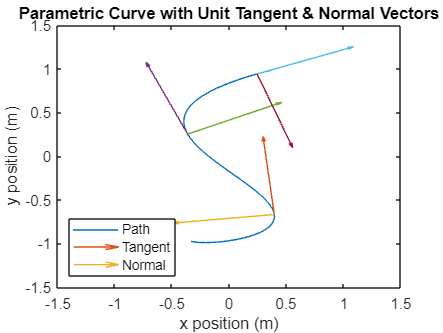

% Exercise 10.1
u = 0:0.01:3.2;
r_u = [0.3960 * cos(2.65 * (u + 1.4)); %i
       -0.99 * sin(u + 1.4)];%j   u ∈ [0, 3.2]

% r(u) = 0.3960 cos(2.65(u + 1.4))ˆi − 0.99 sin(u + 1.4)ˆj, u ∈ [0, 3.2]
figure
plot(r_u(1,:), r_u(2,:))

for u_selected=1:3 % u values where unit tangent vectors are shown
    % plot unit tangent vectors
    
    syms u
    
    r_u = [0.3960 * cos(2.65 * (u + 1.4)); %i
           -0.99 * sin(u + 1.4)];%j   u ∈ [0, 3.2]
    
    r_u_selected = [0.3960 * cos(2.65 * (u_selected + 1.4)); %i
           -0.99 * sin(u_selected + 1.4)];%j   u ∈ [0, 3.2]
    
    dr_du = [diff(r_u(1,:));
            diff(r_u(2,:))];
    T_hat = dr_du./norm(dr_du);

    x_component = vpa(subs(dr_du(1,:),u,u_selected));
    y_component = vpa(subs(dr_du(2,:),u,u_selected));
    magnitude = sqrt(x_component^2 + y_component^2);
    
    hold on
    quiver(r_u_selected(1,:), r_u_selected(2,:), x_component / magnitude, y_component / magnitude);
    
    % plot unit normal vector
    % d2r_du2 = [diff(dr_du(1,:));
    %            diff(dr_du(2,:))]

    d2r_du2 = diff(T_hat);

    x_component_diff = vpa(subs(d2r_du2(1,:),u,u_selected));
    y_component_diff = vpa(subs(d2r_du2(2,:),u,u_selected));
    magnitude2 = sqrt(x_component_diff^2 + y_component_diff^2);

    quiver(r_u_selected(1,:), r_u_selected(2,:), x_component_diff / magnitude2, y_component_diff / magnitude2)

    xlim([-1.5, 1.5])
    ylim([-1.5, 1.5])
    
end

title("Parametric Curve with Unit Tangent & Normal Vectors")
xlabel("x position (m)")
ylabel("y position (m)")
legend("Path", "Tangent", "Normal", 'Location', 'Southwest')
hold off

% Exercise 10.2
beta = 0.16;
time_plot = 0:0.1:20;

syms time

r_t = [0.3960 * cos(2.65 * (beta * time + 1.4)); %i
       -0.99 * sin(beta * time + 1.4)];%j   beta * time ∈ [0, 3.2]

dr_dt = [diff(r_t(1,:));
         diff(r_t(2,:))];

T_hat = dr_dt / norm(dr_dt);

dT_dt = [diff(T_hat(1));
        diff(T_hat(2))];

ang_v = cross([T_hat; 0], [dT_dt; 0]);
ang_velocity = ang_v(3);
lin_velocity = norm(dr_dt);

lin_v_plot = vpa(subs(lin_velocity,time,time_plot));
ang_v_plot = vpa(subs(ang_velocity,time,time_plot));

% each wheel
d = 0.245;

v_l = lin_velocity - ang_velocity * d / 2;
v_r = lin_velocity + ang_velocity * d / 2;

v_l_plot = lin_v_plot - ang_v_plot * d / 2;
v_r_plot = lin_v_plot + ang_v_plot * d / 2;

% Comparing predicted vs. actual
copy_encoder_data = [];
for i = 2:length(encoder_data(:, 1))
    if encoder_data(i, 2)~=encoder_data(i-1, 2)
        copy_encoder_data = [copy_encoder_data; encoder_data(i, :)];
    end
end

delta_t = diff(copy_encoder_data(:,1));

vl = diff(copy_encoder_data(:,2)) ./ delta_t;
vr = diff(copy_encoder_data(:,3)) ./ delta_t;
time_encoder = copy_encoder_data(1:end-1, 1);

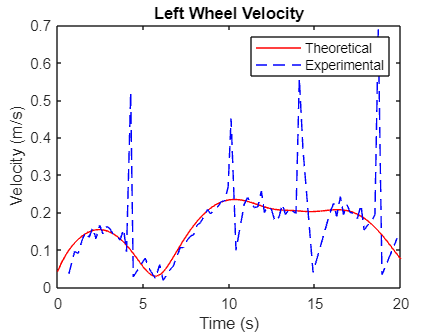

figure
plot(time_plot, v_l_plot, "r")
hold on;
plot(time_encoder, vl, "--b")
title("Left Wheel Velocity")
xlabel("Time (s)")
ylabel("Velocity (m/s)")
legend("Theoretical", "Experimental")
hold off

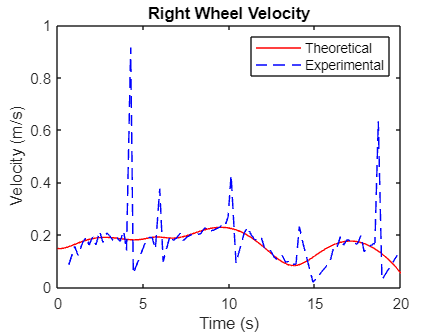


plot(time_plot, v_r_plot, "r")
hold on;
plot(time_encoder, vr, "--b")
title("Right Wheel Velocity")
xlabel("Time (s)")
ylabel("Velocity (m/s)")
legend("Theoretical", "Experimental")
hold off

vel = (vl + vr) / 2;
ang_vel = (vr - vl) / d;

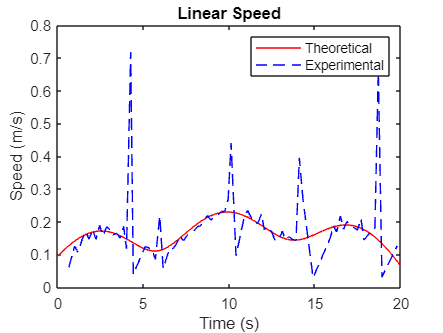

plot(time_plot, lin_v_plot, "r")
hold on;
plot(time_encoder, vel, "--b")
title("Linear Speed")
xlabel("Time (s)")
ylabel("Speed (m/s)")
legend("Theoretical", "Experimental")
hold off

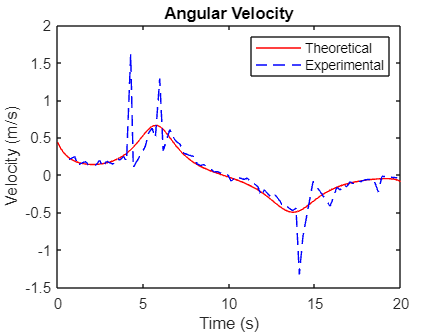


plot(time_plot, ang_v_plot, "r")
hold on;
plot(time_encoder, ang_vel, "--b")
title("Angular Velocity")
xlabel("Time (s)")
ylabel("Velocity (m/s)")
legend("Theoretical", "Experimental")
hold off

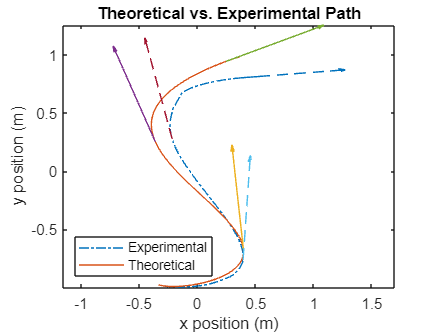

theta = zeros(length(delta_t),1);
theta(1) = -0.25;
    % starting theta value that we thought looked about right
position = zeros(length(delta_t),2);
position(1,:) = [vpa(subs(r_u(1,:),u,0)), vpa(subs(r_u(2,:),u,0))];
    % set starting point to same as r_u(0)
for t=2:(length(delta_t))
    theta(t) = theta(t-1) + ang_vel(t-1) .* delta_t(t-1);
    position(t, :) = [position(t-1,1) + vel(t-1) .* cos(theta(t-1)) .* delta_t(t-1), position(t-1,2) + vel(t-1) .* sin(theta(t-1)) .* delta_t(t-1)];
end

figure()
plot(position(:,1), position(:,2), "-.")
axis equal
hold on

% theoretical plot and tangent vectors
u = 0:0.01:3.2;
r_u_plot = [0.3960 * cos(2.65 * (u + 1.4)); %i
       -0.99 * sin(u + 1.4)];%j   u ∈ [0, 3.2]
plot(r_u_plot(1,:), r_u_plot(2,:))


syms u
r_u = [0.3960 * cos(2.65 * (u + 1.4)); %i
       -0.99 * sin(u + 1.4)];%j   u ∈ [0, 3.2]

dr_du = [diff(r_u(1,:));
            diff(r_u(2,:))];
T_hat = dr_du./norm(dr_du);

for u_selected=1:3
    % plot unit tangent vector
    %u_selected = 3; % change this to change which point the graph
    %                 shows the unit vectors of
    
    r_u_selected = [0.3960 * cos(2.65 * (u_selected + 1.4)); %i
           -0.99 * sin(u_selected + 1.4)];%j   u ∈ [0, 3.2]

    x_component = vpa(subs(dr_du(1,:),u,u_selected));
    y_component = vpa(subs(dr_du(2,:),u,u_selected));
    magnitude = sqrt(x_component^2 + y_component^2);
    
    hold on
    quiver(r_u_selected(1,:), r_u_selected(2,:), x_component / magnitude, y_component / magnitude);
end


% plot unit tangent vectors of the experimental data
sum = 0;
indices = zeros(3,1);
for index=1:length(delta_t) % find tan vector starting points on experimental graph 
                            % corresponding to the starting points on the 
                            % theoretical graph
    sum = sum + delta_t(index);
    if sum < 6.25 % t value where u = 1, 1/beta = 1/0.16 = 6.25
        indices(1,:) = index;
    elseif sum < 12.5 % u=2
        indices(2,:) = index;
    elseif sum < 18.75 % u=3
        indices(3,:) = index;
    end
end


dposition_dt = [diff(position(:, 1)), diff(position(:, 2))];
dpos_norm = dposition_dt ./ norm(dposition_dt);

for u_selected=1:3
    % plot unit tangent vector

    r_u_selected = [position(indices(u_selected), 1); position(indices(u_selected), 2)];

    x_component = dposition_dt(indices(u_selected), 1);
    y_component = dposition_dt(indices(u_selected), 2);
    magnitude = sqrt(x_component^2 + y_component^2);
    
    hold on
    quiver(r_u_selected(1,:), r_u_selected(2,:), x_component / magnitude, y_component / magnitude, "--");
end

title("Theoretical vs. Experimental Path")
xlabel("x position (m)")
ylabel("y position (m)")
legend("Experimental", "Theoretical", 'Location', "Southwest")
hold off